c = 2.99e8;
W = 200e-9;
w = 0.5e-9;
F = c*W/(1300e-9)^2;
f = c*w/(1300e-9)^2;

lo = c/F;
L = c/f;

Wc = 1300e-9;
Fstart = c/(Wc+W/2);
Fend = c/(Wc-W/2);
Fc = (Fend+Fstart)/2;
N = round(F/f)/2;

lo = c/F;
L = N*lo;

lvec = 0:lo:lo*(N-1);
fvec = Fc-f*(N-1):f:Fc+f*(N-1);

p1 = 0.4*N+1;
p2 = 0.4*N+3;
p3 = 0.89*N;
a = zeros(2*N-1,1);
a(p1) = 1;
a(p2) = 1;

a(p3) = 0.8;

a(2*N+1-p1) = 1;
a(2*N+1-p2) = 1;

a(2*N+1-p3) = 0.8;

%%%%%%%%%%% SD OCT %%%%%%%%%%%%%%

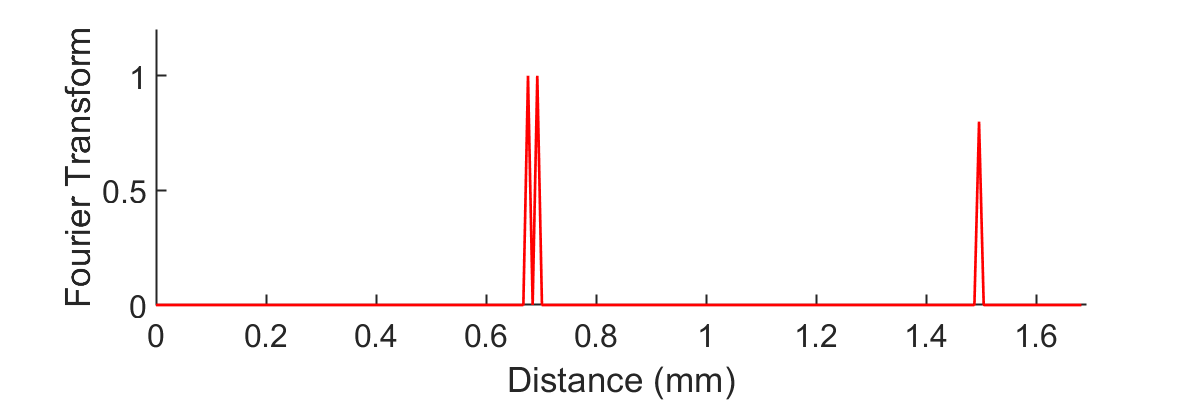

figure; hold on;
plot(lvec*1000,a(1:N),'LineWidth',2,'Color','r')

ylabel('Fourier Transform')
xlabel('Distance (mm)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
ylim([0 1.2])
xlim([0 L]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 1200 400])

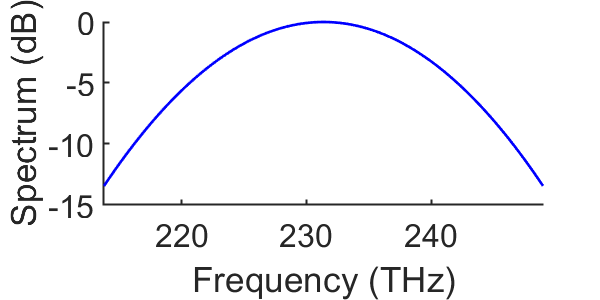

lvecs = 1:1:2*N-1;
S2 = gaussmf(lvecs,[0.4*N N])';
figure; hold on;
plot(fvec/1e12,10*log10(S2),'LineWidth',2,'Color','b')


ylabel('Spectrum (dB)')
xlabel('Frequency (THz)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
%ylim([0 1.2])
xlim([Fc-f*(N-1) Fc+f*(N-1)]/1e12)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 600 300])

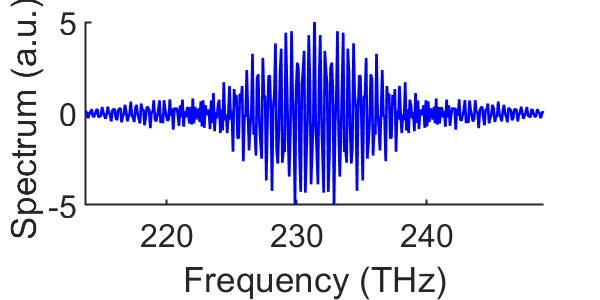

PSD = S2.*fftshift(fft(a));
figure; hold on;
plot(fvec/1e12,real(PSD),'LineWidth',2,'Color','b')

ylabel('Spectrum (a.u.) ')
xlabel('Frequency (THz)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
ylim([-5 5])
xlim([Fc-f*(N-1) Fc+f*(N-1)]/1e12)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 600 300])

%%%%%%%%% Delay line %%%%%%%%%%

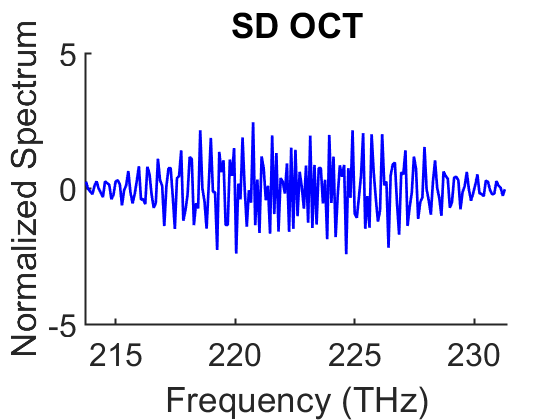

A = fft(a);
PSD_half = S2(1:2:end-1).*A(1:N-1);

figure; hold on;
plot(fvec(1:N-1)/1e12,real(PSD_half),'LineWidth',2,'Color','b')

ylabel('Normalized Spectrum')
xlabel('Frequency (THz)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
ylim([-5 5])
xlim([Fc-f*(N-1) Fc]/1e12)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
title('SD OCT')

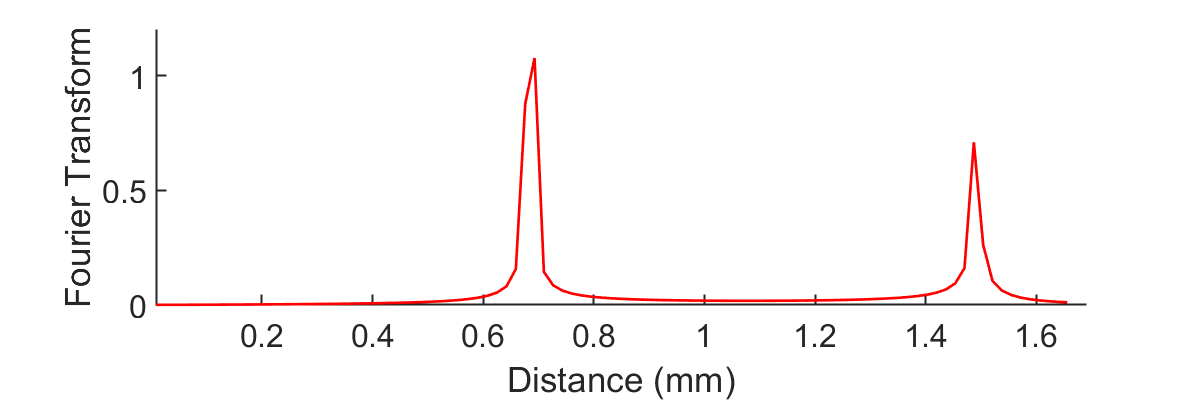

Acap1 = PSD_half./S2(1:2:end-1);
a1 = ifft(Acap1);

figure; hold on;
plot(lvec(1:2:end-2)*1000,abs(a1(1:N/2-1)),'LineWidth',2,'Color','r')

ylabel('Fourier Transform')
xlabel('Distance (mm)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
ylim([0 1.2])
xlim([lo L]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 1200 400])

delay = exp(1i*2*pi*lo*fvec(1:N-1)/(2*c));
Acap2 = Acap1.*delay';

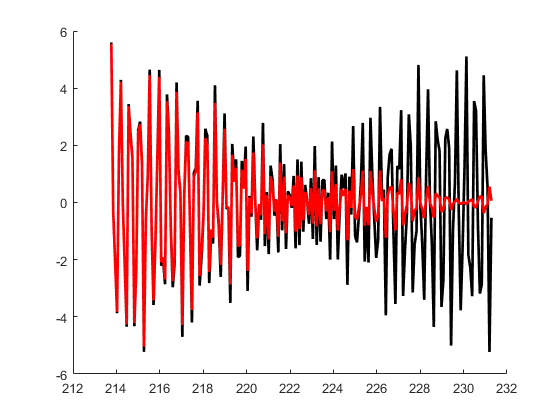

figure; hold on;
plot(fvec(1:N-1)/1e12,real(Acap1),'LineWidth',2,'Color','k')
plot(fvec(1:N-1)/1e12,real(Acap2),'LineWidth',2,'Color','r')

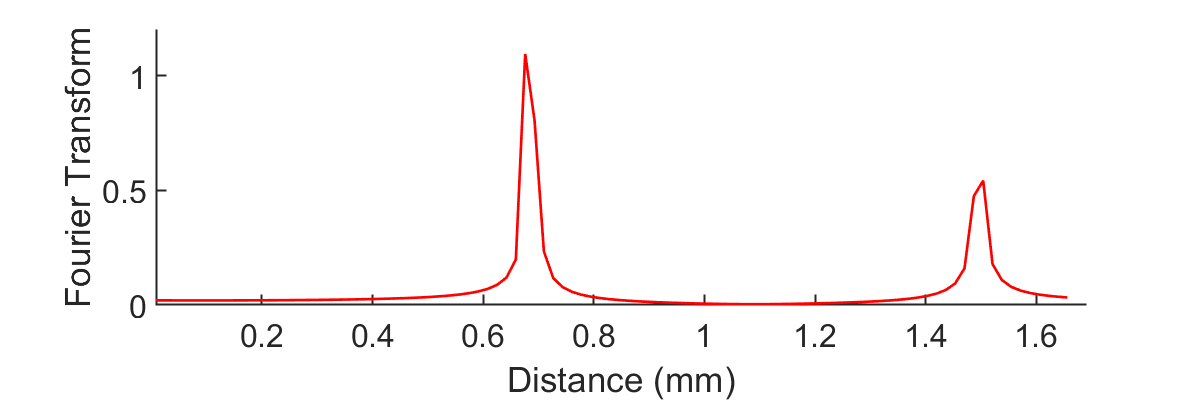

a2 = ifft(Acap2);

figure; hold on;
plot(lvec(1:2:end-2)*1000,abs(a2(1:N/2-1)),'LineWidth',2,'Color','r')

ylabel('Fourier Transform')
xlabel('Distance (mm)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
ylim([0 1.2])
xlim([lo L]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 1200 400])

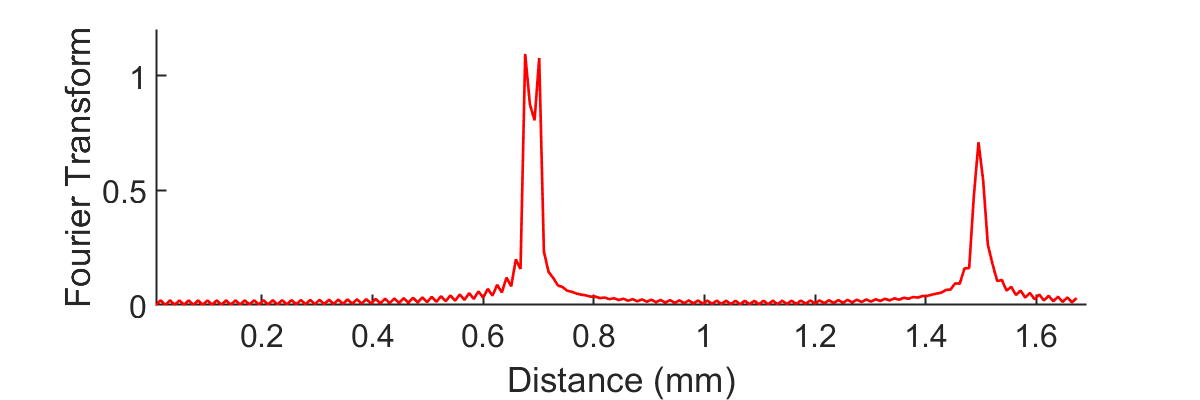

a_rec = zeros(2*N-2,1);
a_rec(1:2:end) = a2;
a_rec(2:2:end) = a1;

figure; hold on;
plot(lvec(1:end-1)*1000,abs(a_rec(1:N-1)),'LineWidth',2,'Color','r')

ylabel('Fourier Transform')
xlabel('Distance (mm)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
ylim([0 1.2])
xlim([lo L]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 1200 400])

%%%%%%%% Cross-arm phase modulation %%%%%%%%

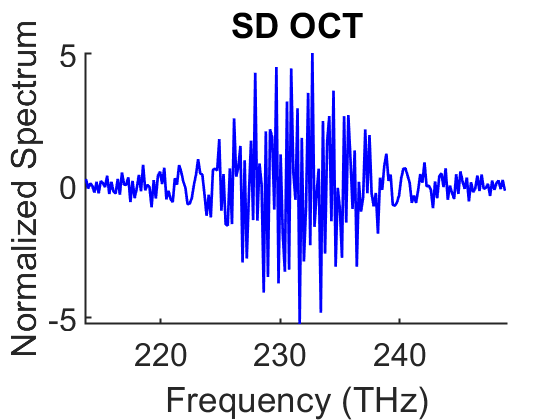

PSD_downsample = S2(1:2:end-1).*A(1:2:2*N-2);

figure; hold on;
plot(fvec(1:2:2*N-2)/1e12,real(PSD_downsample),'LineWidth',2,'Color','b')

ylabel('Normalized Spectrum')
xlabel('Frequency (THz)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
%ylim([-5 5])
xlim([Fc-f*(N-1) Fc+f*(N-1)]/1e12)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
title('SD OCT')

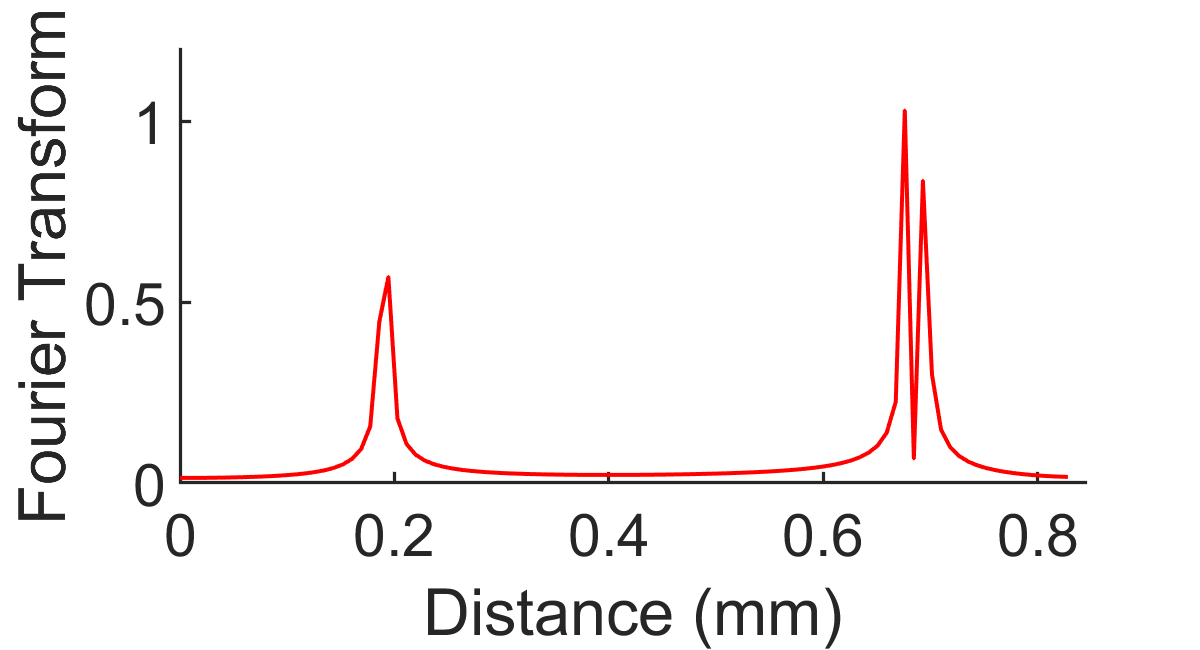

%Acap_d = A(1:2:2*N-2);
a_det = ifft(PSD);
a_d = ifft(A(1:2:2*N-1));
figure; hold on;
plot(lvec(1:N/2-1)*1000,abs(a_d(1:N/2-1)),'LineWidth',3,'Color','r')

ylabel('Fourier Transform')
xlabel('Distance (mm)')
%lgd = legend('Channel 0','Channel 1');
%lgd.FontSize = 12;
ylim([0 1.2])
xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('SD OCT')
set(gcf,'Position',[0 0 1200 650])

%tau_vec = (-1*lo*(N-1):lo:lo*(N-1)*1)/c;
A1 = 2;
A2 = 1;
f11 = f/4;
f12 = f/2;
f21 = f/4;
f22 = f/2;

% H0 = besselj(0,2*A1*sin(pi*f21*tau_vec));
% H1 = besselj(0,2*A2*sin(pi*f12*tau_vec));
% H0n = fftshift(H0);
% H1n = fftshift(H1);
% 
% H0nc = besselj(0,2*A1*cos(pi*f12*tau_vec));
% figure;
% plot(f12*tau_vec);
% figure;
% subplot(2,1,1)
% hold on;
% % plot(real(Mod1));
% % plot(real(Mod2));
% %plot(real(r12));
% %plot(abs(r12));
% plot(real(H0n));
% plot(real(H0nc));
% %plot(real(H0c));
% subplot(2,1,2)
% hold on;
% plot(real(H1).*real(H1n));

tau_vec = (-10*lo*(N-1):lo:10*lo*(N-1))/c;
Mod11 = exp(1i*A1*sin(2*pi*f11*tau_vec));
Mod12 = exp(1i*A1*sin(2*pi*f12*tau_vec));
r0 = xcorr(Mod11,Mod12,'unbiased');
H0 = r0((size(r0,2)+1)/2-N+1:(size(r0,2)+1)/2+N-1);

Mod21 = exp(1i*A2*sin(2*pi*f21*tau_vec));
Mod22 = exp(1i*A2*sin(2*pi*f22*tau_vec));
r1 = xcorr(Mod21,Mod22,'unbiased');
H1 = r1((size(r1,2)+1)/2-N+1:(size(r1,2)+1)/2+N-1);

H0n = fftshift(H0);
H1n = fftshift(H1);

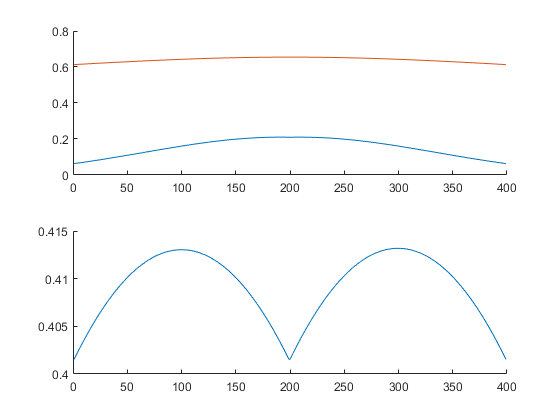


figure;
subplot(2,1,1)
hold on;
% plot(real(Mod1));
% plot(real(Mod2));
%plot(real(r12));
%plot(abs(r12));
plot(real(H0));
plot(real(H1));
%plot(real(H0c));
subplot(2,1,2)
hold on;
plot(real(H1).*real(H1n));

h0 = fftshift(ifft(ifftshift(H0)));
h0n = fftshift(ifft(ifftshift(H0n)));

h1 = fftshift(ifft(ifftshift(H1)));
h1n = fftshift(ifft(ifftshift(H1n)));

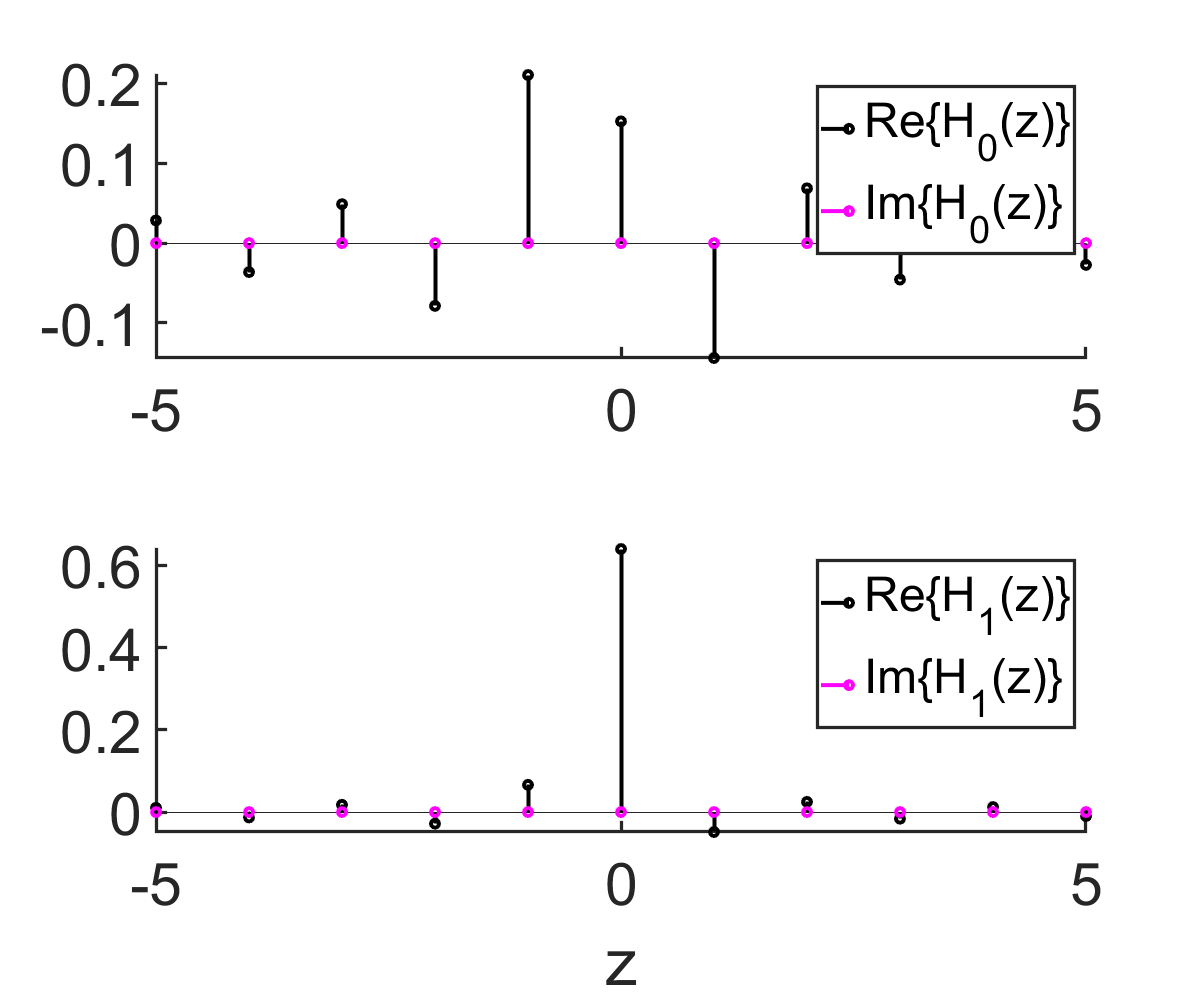



figure;
subplot(2,1,1);
hold on;
stem(-5:5,real(h0(200-5:200+5)),'LineWidth',3,'Color','k');
stem(-5:5,imag(h0(200-5:200+5)),'LineWidth',3,'Color','m');

lgd = legend('Re\{H_0(z)\}','Im\{H_0(z)\}');
lgd.FontSize = 36;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('Filter')


subplot(2,1,2);
hold on;
stem(-5:5,real(h1(200-5:200+5)),'LineWidth',3,'Color','k');
stem(-5:5,imag(h1(200-5:200+5)),'LineWidth',3,'Color','m');

lgd = legend('Re\{H_1(z)\}','Im\{H_1(z)\}');
lgd.FontSize = 36;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('Filter')
xlabel('z')
set(gcf,'Position',[0 0 1200 1000])

% h0 = fftshift(ifft(ifftshift(H0)));
% h0n = fftshift(ifft(H0));
% 
% h1 = fftshift(ifft(ifftshift(H1)));
% h1n = fftshift(ifft(H1));
% 
% figure;
% %subplot(2,1,1);
% hold on;
% stem(-20:20,real(h0(200-20:200+20)),'LineWidth',2,'Color','r');
% stem(-20:20,real(h1(200-20:200+20)),'LineWidth',2,'Color','b');
% 
% lgd = legend('H_0(z)','H_1(z)');
% lgd.FontSize = 12;
% %xlim([0 L/2]*1000)
% % grid on;
% % grid minor;
% set(gca,'FontSize',24)
% set(gca,'linewidth',1.5)
% title('Filter')
% 
% % subplot(2,1,2);
% % hold on;
% % stem(-20:20,real(h1(200-20:200+20)),'LineWidth',2,'Color','r');
% % stem(-20:20,real(h1n(200-20:200+20)),'LineWidth',2,'Color','b');
% % xlabel('Sample')
% % set(gca,'FontSize',24)
% % set(gca,'linewidth',1.5)

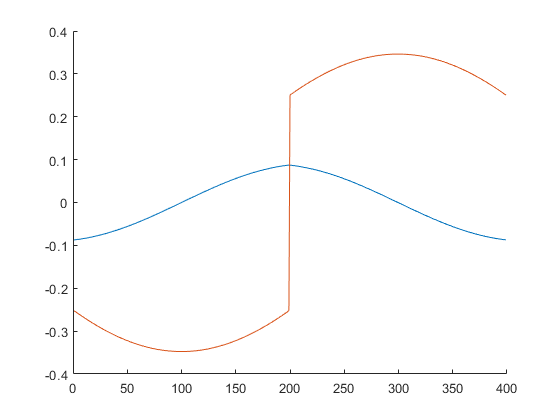

Delta = H0.*H1n-H0n.*H1;

figure;
%subplot(2,1,1);
hold on;
plot(real(Delta))
plot(imag(Delta))

%stem(-20:20,real(Delta(100-20:100+20)),'LineWidth',2,'Color','r');

% lgd = legend('H_0(z)','H_1(z)');
% lgd.FontSize = 12;
% xlim([0 L/2]*1000)
% grid on;
% grid minor;
% set(gca,'FontSize',24)
% set(gca,'linewidth',1.5)
% title('\Delta(z)')

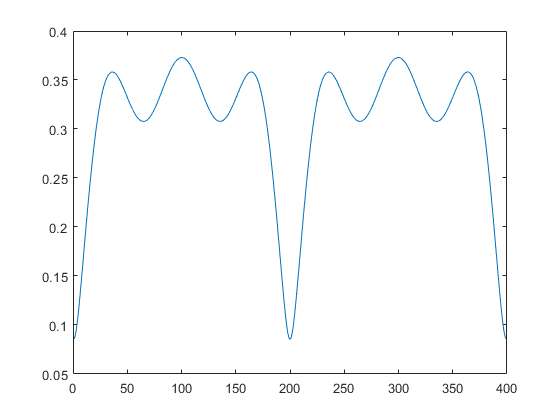

delta_temp = fftshift(ifft(ifftshift(Delta)));
delta = delta_temp(200-5:200+5);
%figure; stem(delta)
[z,p,k] = tf2zpk(delta,1);
%abs(z)
[z,p,k] = tf2zpk(polystab(delta)*norm(delta)/norm(polystab(delta)),1);
%abs(z)
for i = 1:10
    if abs(z(i)) >0.95
        z(i) = z(i)*0.95/abs(z(i));
    end
end
%abs(z)
delta_st = zp2tf(z,p,k);
%figure; stem(delta_st);
delta_s = zeros(2*N-1,1);
delta_s(N-5:N+5) = delta_st;
Delta_s = fftshift(fft(ifftshift(delta_s)));
figure;
plot(abs(Delta_s));

U0 = a_det.*ifftshift(H0)';
U1 = a_det.*ifftshift(H1)';

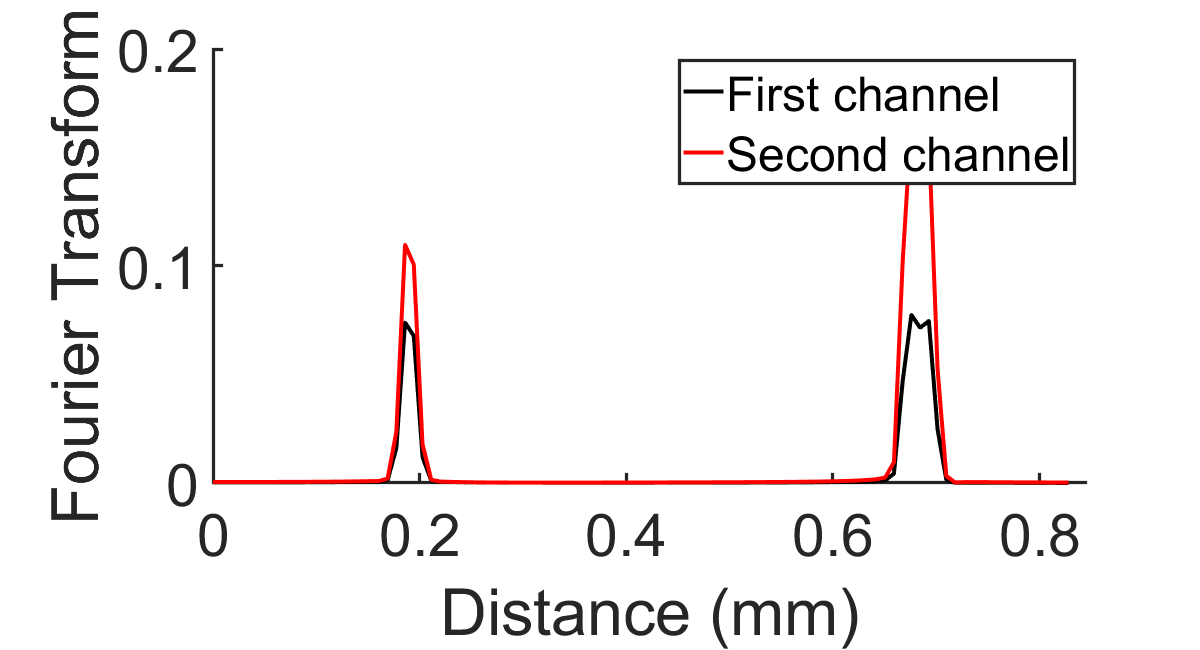

u0 = ifft(U0);
u0d = u0(1:2:end-1);
u1 = ifft(U1);
u1d = u1(1:2:end-1);

U0d = fft(u0d);
U1d = fft(u1d);

figure; hold on;
plot(lvec(1:N/2-1)*1000,abs(U0d(1:N/2-1)),'LineWidth',3,'Color','k');
plot(lvec(1:N/2-1)*1000,abs(U1d(1:N/2-1)),'LineWidth',3,'Color','r');

lgd = legend('First channel','Second channel');
lgd.FontSize = 36;
xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('Filter')
xlabel('Distance (mm)')
ylabel('Fourier Transform')
set(gcf,'Position',[0 0 1200 650])

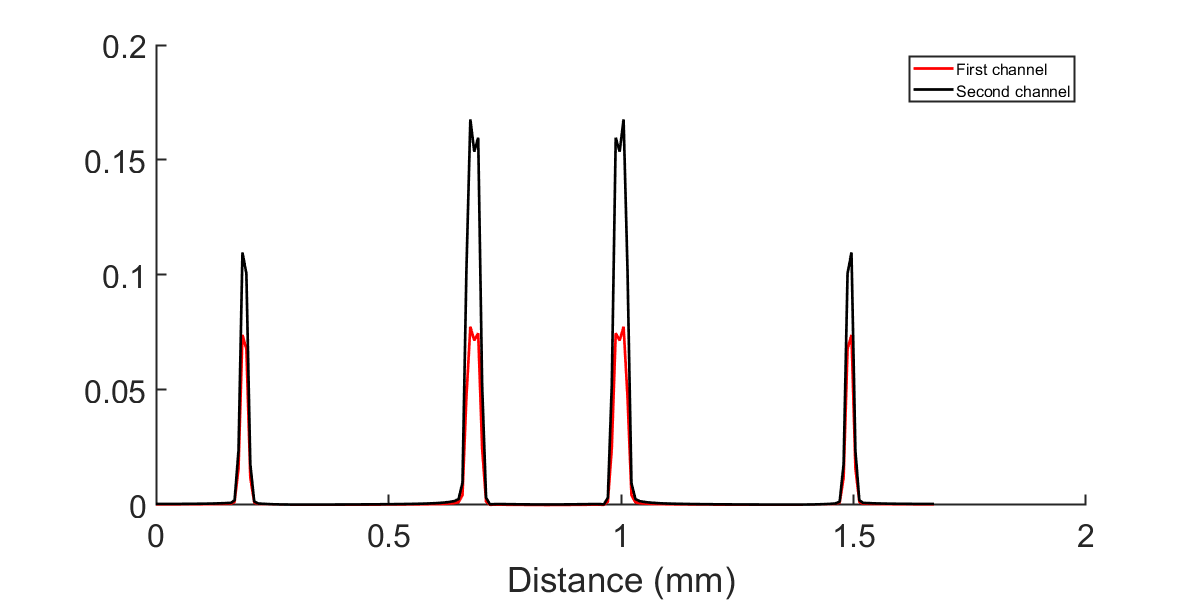

u0u = zeros(2*N-2,1);
u0u(1:2:2*N-2) = u0d;
u1u = zeros(2*N-2,1);
u1u(1:2:2*N-2) = u1d;

U0u = fft(u0u);
U1u = fft(u1u);
figure; hold on;
plot(lvec(1:N-1)*1000,abs(U0u(1:N-1)),'LineWidth',2,'Color','r');
plot(lvec(1:N-1)*1000,abs(U1u(1:N-1)),'LineWidth',2,'Color','k');
lgd = legend('First channel','Second channel');
lgd.FontSize = 12;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('Filter')
xlabel('Distance (mm)')
set(gcf,'Position',[0 0 1200 600])

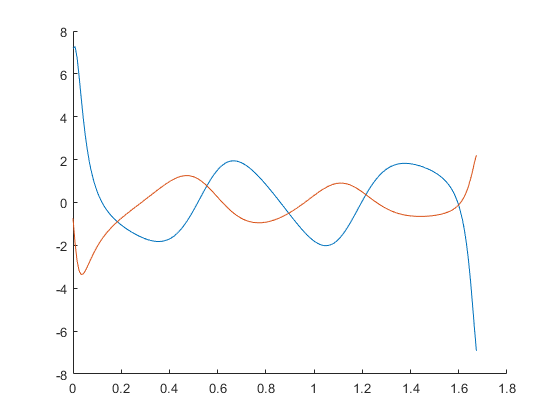

F0 = ifftshift(H1n./Delta_s');
F1 = ifftshift(-H0n./Delta_s');
figure; hold on;
plot(lvec(1:N-1)*1000,real(F0(1:N-1)));
plot(lvec(1:N-1)*1000,real(F1(1:N-1)));

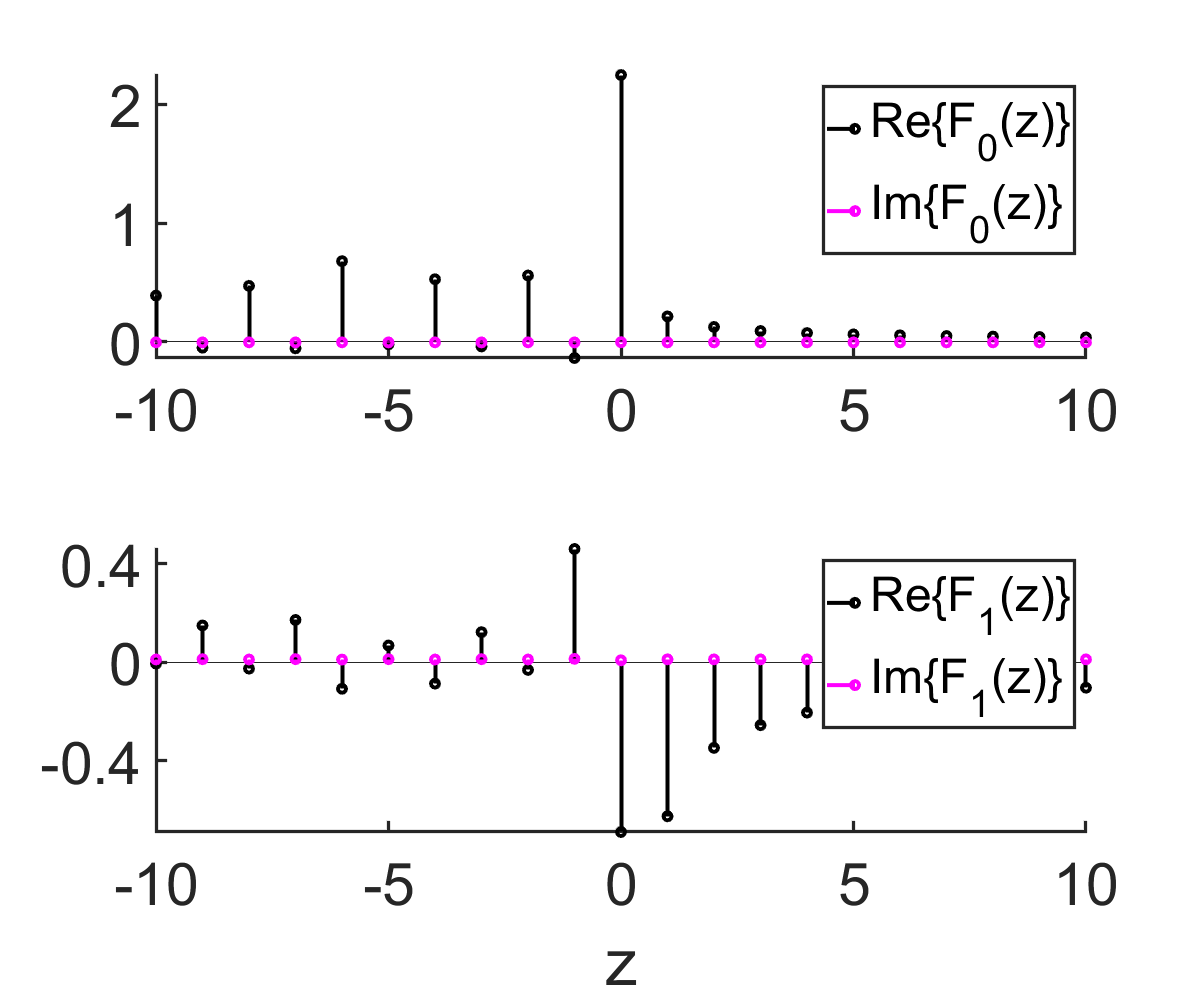

f0 = fftshift(ifft(F0));
f1 = fftshift(ifft(F1));


figure;
subplot(2,1,1);
hold on;
stem(-10:10,real(f0(195-10:195+10)),'LineWidth',3,'Color','k');
stem(-10:10,imag(f0(195-10:195+10)),'LineWidth',3,'Color','m');

lgd = legend('Re\{F_0(z)\}','Im\{F_0(z)\}');
lgd.FontSize = 36;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('Filter')


subplot(2,1,2);
hold on;
stem(-10:10,real(f1(195-10:195+10)),'LineWidth',3,'Color','k');
stem(-10:10,imag(f1(195-10:195+10)),'LineWidth',3,'Color','m');

lgd = legend('Re\{F_1(z)\}','Im\{F_1(z)\}');
lgd.FontSize = 36;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('Filter')
xlabel('z')
set(gcf,'Position',[0 0 1200 1000])
yticks([-0.4 0 0.4])

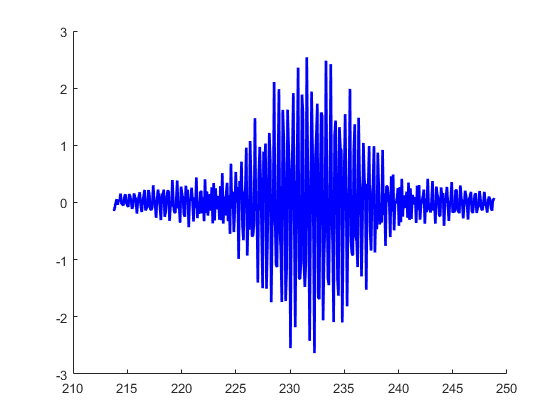

Yc = F0(1:2*N-2).*U0u'+F1(1:2*N-2).*U1u';
yc = fft(Yc);
figure;hold on;
plot(fvec(1:end-1)/1e12,real(yc),'LineWidth',2,'Color','b')

ycn = yc./S2(1:end-1)';
Ycn = ifft(ycn);

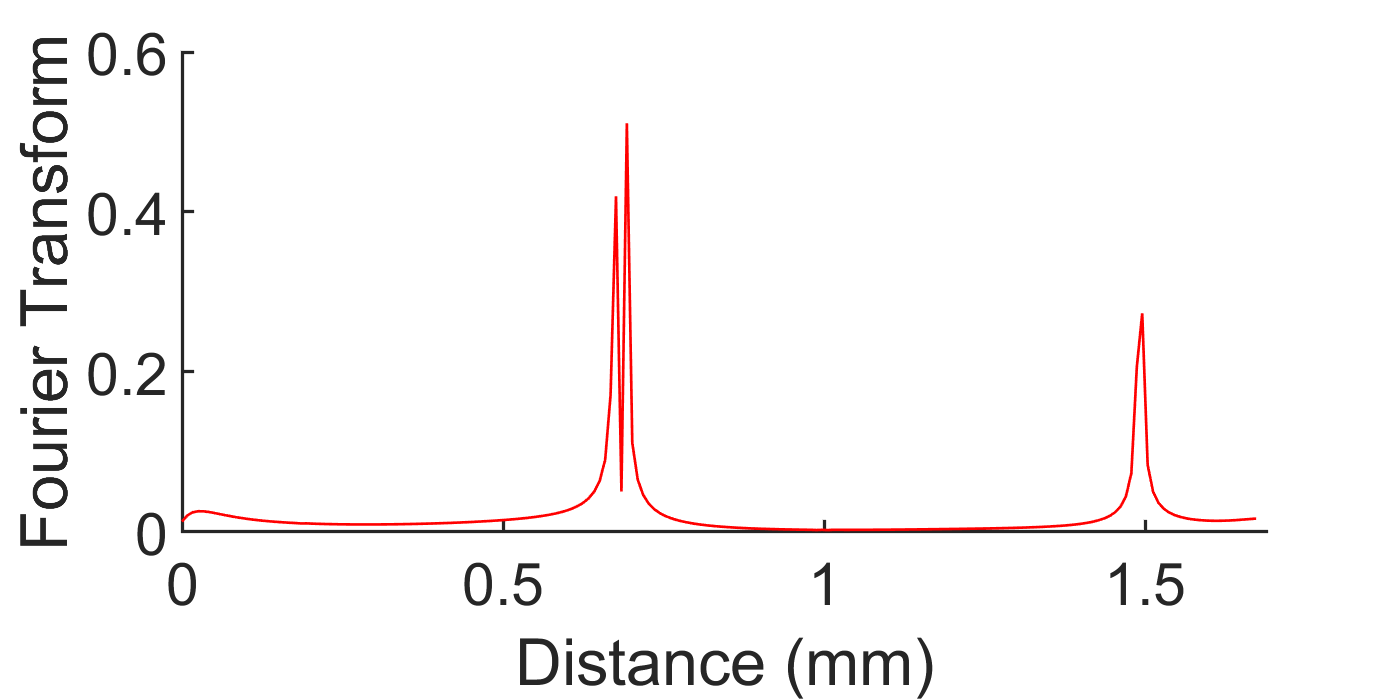

figure;hold on;
plot(lvec(1:N-1)*1000,abs(Ycn(1:N-1)),'LineWidth',2,'Color','r')
% lgd = legend('First channel','Second channel');
% lgd.FontSize = 12;
xlim([0 L]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('Filter')
xlabel('Distance (mm)')
ylabel('Fourier Transform')
set(gcf,'Position',[0 0 1400 700])